clc; clear; close all;

baseRaw = load("baseRaw.mat");
pendRaw = load("pendRaw.mat");
baseRaw = baseRaw.base;
pendRaw = pendRaw.pend;
dt = 0.005;

time = linspace(1, length(baseRaw)*dt, length(baseRaw))

time =     1.0000    1.0050    1.0099    1.0149    1.0198    1.0248    1.0297    1.0347    1.0396    1.0446    1.0495    1.0545    1.0594    1.0644    1.0693    1.0743    1.0792    1.0842    1.0891    1.0941    1.0991    1.1040    1.1090    1.1139    1.1189    1.1238    1.1288    1.1337    1.1387    1.1436    1.1486    1.1535    1.1585    1.1634    1.1684    1.1733    1.1783    1.1832    1.1882    1.1932    1.1981    1.2031    1.2080    1.2130    1.2179    1.2229    1.2278    1.2328    1.2377    1.2427


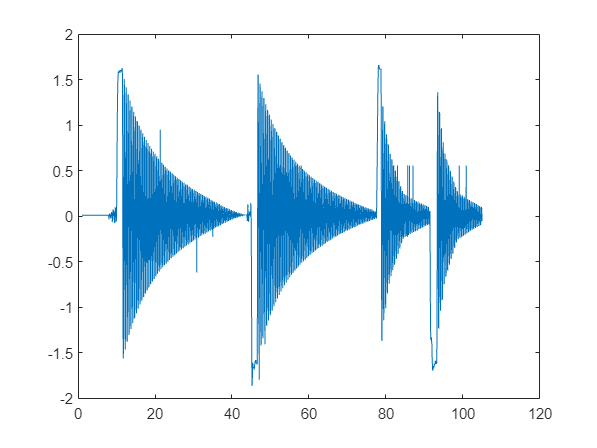


plot(time, pendRaw)

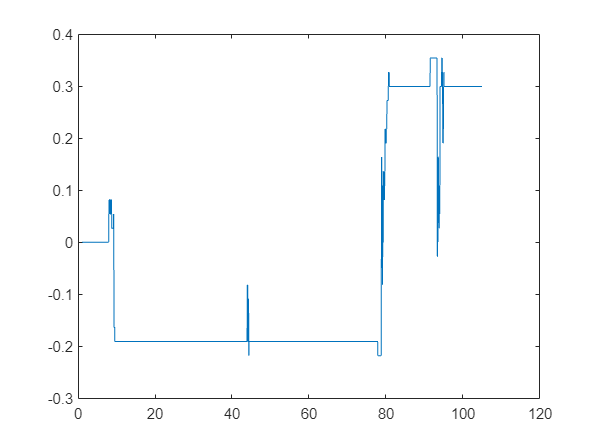

plot(time, baseRaw)


% from 3 locked
pendFirst.angle = pendRaw(10.45/dt:44.5/dt);
pendFirst.time = linspace(1, length(pendFirst.angle)*dt, length(pendFirst.angle));
pendFirst.angle = pendFirst.angle - pendFirst.angle(1);
pendFirst.time = pendFirst.time - pendFirst.time(1);
pendFirst.description = "Dropped from 3 a clock, base locked"

pendFirst = struct with fields:
          angle: [6811×1 double]
           time: [0 0.0049 0.0097 0.0146 0.0194 0.0243 0.0291 0.0340 0.0388 0.0437 0.0485 0.0534 0.0582 0.0631 0.0680 0.0728 0.0777 0.0825 0.0874 0.0922 0.0971 0.1019 0.1068 0.1116 0.1165 0.1213 0.1262 0.1311 0.1359 0.1408 0.1456 0.1505 0.1553 0.1602 … ]
    description: "Dropped from 3 a clock, base locked"


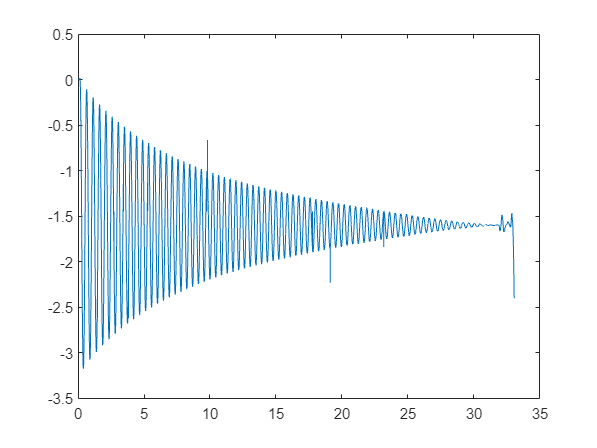

plot(pendFirst.time, pendFirst.angle)


% from 9 locked
pendSecond.angle = pendRaw(46.5/dt:77.5/dt);
pendSecond.time = linspace(1, length(pendSecond.angle)*dt, length(pendSecond.angle));
pendSecond.angle = pendSecond.angle - pendSecond.angle(1);
pendSecond.time = pendSecond.time - pendSecond.time(1);
pendSecond.description = "Dropped from 9 a clock, base locked"

pendSecond = struct with fields:
          angle: [6201×1 double]
           time: [0 0.0048 0.0097 0.0145 0.0194 0.0242 0.0290 0.0339 0.0387 0.0436 0.0484 0.0532 0.0581 0.0629 0.0678 0.0726 0.0774 0.0823 0.0871 0.0920 0.0968 0.1016 0.1065 0.1113 0.1161 0.1210 0.1258 0.1307 0.1355 0.1403 0.1452 0.1500 0.1549 0.1597 … ]
    description: "Dropped from 9 a clock, base locked"


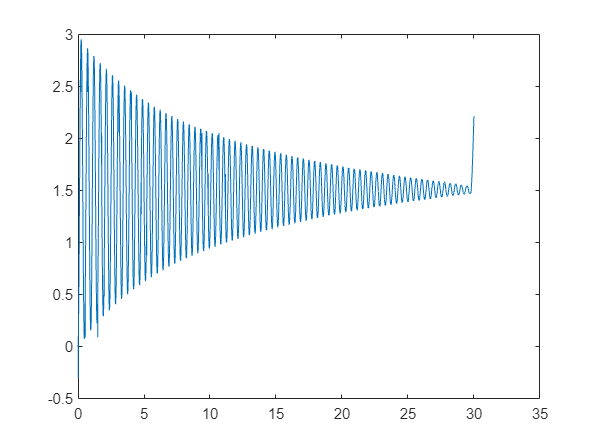

plot(pendSecond.time, pendSecond.angle)


% from 3 free
pendThird.angle = pendRaw(round(78.4/dt):round(91.4/dt));
pendThird.time = linspace(1, length(pendThird.angle)*dt, length(pendThird.angle));
pendThird.angle = pendThird.angle - pendThird.angle(1);
pendThird.baseAngle = baseRaw(round(78.4/dt):round(91.4/dt));
pendThird.time = pendThird.time - pendThird.time(1);
pendThird.description = "Dropped from 3 a clock, base is free to move"

pendThird = struct with fields:
          angle: [2601×1 double]
           time: [0 0.0046 0.0092 0.0139 0.0185 0.0231 0.0277 0.0323 0.0369 0.0416 0.0462 0.0508 0.0554 0.0600 0.0646 0.0693 0.0739 0.0785 0.0831 0.0877 0.0923 0.0970 0.1016 0.1062 0.1108 0.1154 0.1200 0.1247 0.1293 0.1339 0.1385 0.1431 0.1478 0.1524 … ]
      baseAngle: [2601×1 double]
    description: "Dropped from 3 a clock, base is free to move"


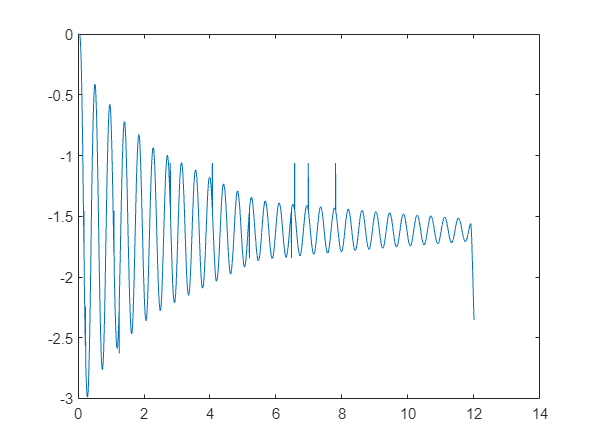

plot(pendThird.time, pendThird.angle)

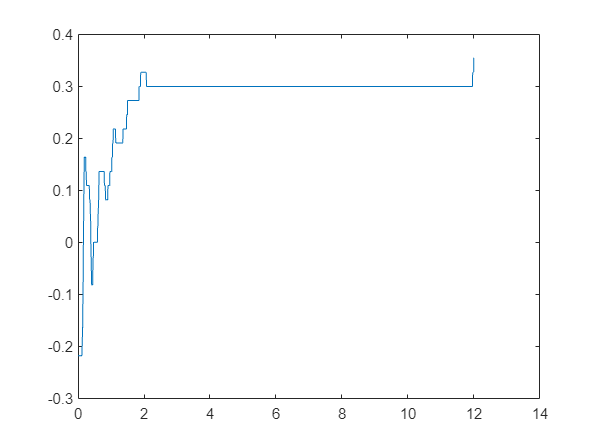

plot(pendThird.time, pendThird.baseAngle)


% from 3 free
pendFourth.angle = pendRaw(round(93.2/dt):round(104.9/dt));
pendFourth.time = linspace(1, length(pendFourth.angle)*dt, length(pendFourth.angle));
pendFourth.angle = pendFourth.angle - pendFourth.angle(1);
pendFourth.baseAngle = baseRaw(round(93.2/dt):round(104.9/dt));
pendFourth.time = pendFourth.time - pendFourth.time(1);
pendFourth.description = "Dropped from 9 a clock, base is free to move"

pendFourth = struct with fields:
          angle: [2341×1 double]
           time: [0 0.0046 0.0091 0.0137 0.0183 0.0229 0.0274 0.0320 0.0366 0.0412 0.0457 0.0503 0.0549 0.0595 0.0640 0.0686 0.0732 0.0778 0.0823 0.0869 0.0915 0.0961 0.1006 0.1052 0.1098 0.1144 0.1189 0.1235 0.1281 0.1327 0.1372 0.1418 0.1464 0.1510 … ]
      baseAngle: [2341×1 double]
    description: "Dropped from 9 a clock, base is free to move"


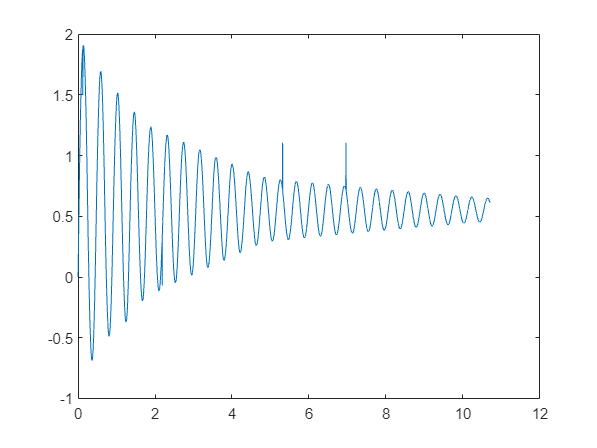

plot(pendFourth.time, pendFourth.angle)

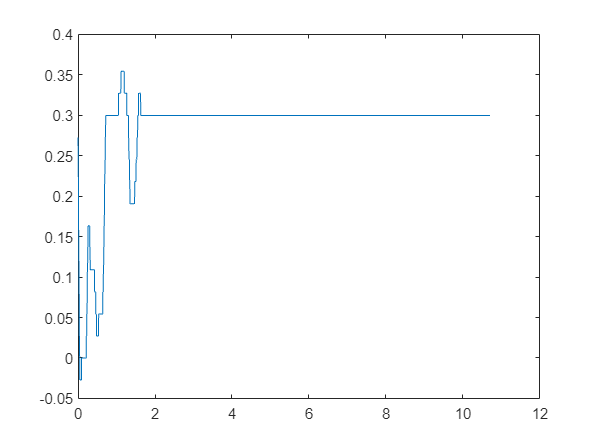

plot(pendFourth.time, pendFourth.baseAngle)